% This is the testing file for scan conversion

fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
B = zeros(h,w);
B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));

B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))

B =      1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     

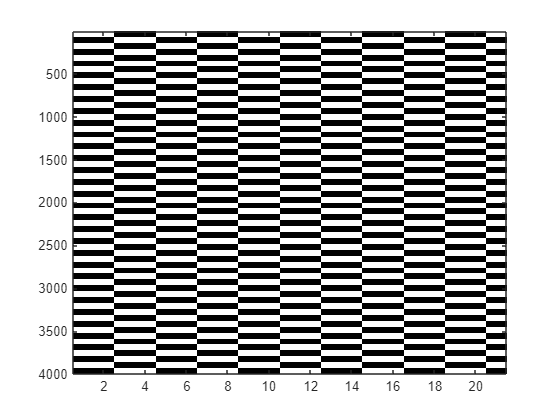



% Make block
% a = 1000
% b = 2000
% c = 6
% d = 8
% 
% B = zeros(h,w);
% B(a:b,c:d) = ones(b-a+1,d-c+1)

figure
colormap(gray)
imagesc(B)


% All ones to view beams
% B = ones(h,w);

imager = 101;
imagec = 201;
ishiftr = floor(imager/2);
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas(1,:) % have spearate lookups for image and for beams??

ans =    -1.5708   -1.1198   -0.9273   -0.7754   -0.6435   -0.5236   -0.4115   -0.3047   -0.2014   -0.1002         0    0.1002    0.2014    0.3047    0.4115    0.5236    0.6435    0.7754    0.9273    1.1198    1.5708





%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs(end,:)

ans =    22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143   22.7143




%precompute image rvals
rvals = zeros(imager,imagec);
for rr=1:imager
    for cc=1:imagec
        r = rr-1;
        c = cc - ishiftc - 1;
        rvals(rr,cc) = sqrt(r^2+c^2)/100;
    end
end
rvals;


% for px = 1:imagec
%     for py = 1:imager
%         r = rvals(py,px);
%         n = floor(r*Fs/c);
% 
%         theta = thetas(py,px);
%         k = floor(sin(theta)/2*Fs/fc);
%         kk = k + shift;
%         if (n < h) && (kk < w)
%             blah = B(n,kk);
%         end
%     end
% end
% n
% k
% blah

image = zeros(imager,imagec);
% Put things in beams onto image

rfpp = (imager-1)/rs(end,1)

rfpp = 4.4025

cfpp = (imagec/2-1)/rs(end,1)

cfpp = 4.3805


aspectRatio = cfpp/rfpp

aspectRatio = 0.9950

tic
for kk = 1:w
    k = kk-shift;
    for n = 1:h
        r = rs(n,kk);
        theta = thetas(n,kk);

        y = floor(r*cos(theta)*rfpp);
        x = round(r*sin(theta)*cfpp);

        image(y+1,x+1+ishiftc) = B(n,kk);
    end
end
time = toc

time = 0.0098

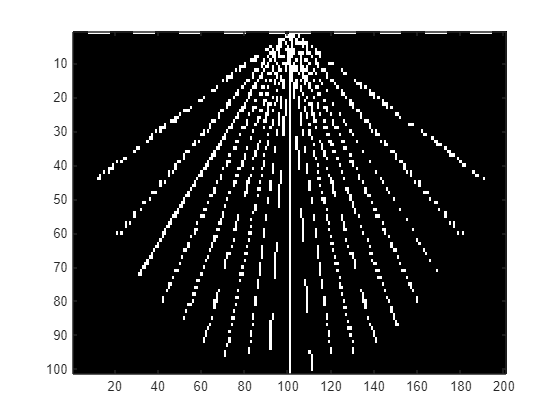

% his time is 0.0466669 but also interpolates



%image = ones(imager,imagec)-image;




figure
colormap(gray)
imagesc(image)



% Now, need to interpolate
image_interp = image;
max_distance = rs(end,1)

max_distance = 22.7143

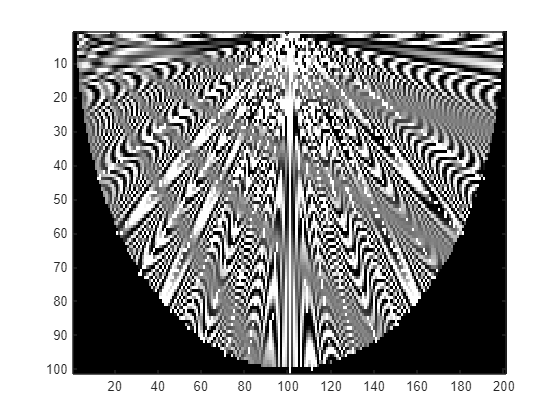


for px = 1:imagec
    for py = 1:imager
        if image_interp(py,px) == 0
            rp = sqrt(((px-1-ishiftc)/cfpp)^2+((py-1)/rfpp)^2);

            if (rp <= .99*max_distance)
                thetap = atan(py/px);
      
                kp =  sin(thetap)/2*Fs/fc;
                k = floor(kp);
                k1 = k+1;
                kk = k+shift;
                kk1 = k1+shift;
        
                np = rp/C*Fs;
                n = floor(np)+1;
                n1 = n+1;
        
                r = rs(n,1);
                r1 = rs(n1,1);
                dr = r1-r;
        
                theta = thetas(1,kk);
                theta1 = thetas(1,kk1);
                dtheta = theta1-theta;
        
                beta = (rp - r)/dr;
                alpha = (thetap - theta)/dtheta;
        
                image_interp(py,px) = (1-beta)*((1-alpha)*B(n,kk)+alpha*B(n,kk1)) + beta*((1-alpha)*B(n1,kk) + alpha*B(n1,kk1));
            else
                image_interp(py,px) = 0;
            end
        end
    end
end

figure
colormap(gray)
imagesc(image_interp)


image_interp;

% compare
test_image = scan_conversion(B, 19, 2000, 10, 100)

Index in position 2 exceeds array bounds. Index must not exceed 21.

Error in scan_conversion


figure
colormap(gray)
imagesc(test_image)

% Figuring out data thing

load sc_image.mat -mat

sc_image

sc_image =   10.000000000000000                   0                   0                   0                   0                   0   6.925880318377913   6.578934899681581  15.438304508223858   4.588324612610002   2.497821835239469   4.538842389941527   1.830506383574379   1.304526653867186   1.786396936046741   1.611697727810480   1.542607697650314   2.552942541497841   1.798914582175006   0.802909638459034   0.836785335421597   1.188300468783487   1.003752215667698   0.470179942662890   0.291966750314886   0.907859656498260   0.794958223648718   0.190008850308847   0.879154789742691   0.549693155088129   0.583171538433274   0.466108218279640   0.640872056916673   0.253554006008627   0.918922802718231   1.395771942886959   0.674295163117886   0.887582387441056   1.195540789112901   2.449219502551708   0.717741209022740   1.134528382644665   1.775078346821175   1.925550440276383   5.583349172848036   3.966183791996426   0.678491762360046   3.277777665353687   0.334165986779212   0.4204


figure
imagesc(sc_image)

% Turning it into a function